# Lab 5

## Kurt Delegard

## PHYS 434 AB

### Time spent drafting: 7 hours

clear;
clc;

h5disp("C:\Users\hsp_x\Desktop\PHYS_434\Lab 5\heradata.uvh5");

HDF5 heradata.uvh5 
Group '/' 
    Group '/Data' 
        Dataset 'flags' 
            Size:  4x1024x1x82680
            MaxSize:  4x1024x1x82680
            Datatype:   H5T_ENUM
                Base Type:  H5T_STD_I8LE
                Member 'FALSE':  0
                Member 'TRUE':  1
            ChunkSize:  1x32x1x2584
            Filters:  unrecognized filter (lzf)
        Dataset 'nsamples' 
            Size:  4x1024x1x82680
            MaxSize:  4x1024x1x82680
            Datatype:   H5T_IEEE_F32LE (single)
            ChunkSize:  1x32x1x1292
            Filters:  unrecognized filter (lzf)
        Dataset 'visdata' 
            Size:  4x1024x1x82680
            MaxSize:  4x1024x1x82680
            Datatype:   H5T_COMPOUND
                Member 'r':  H5T_IEEE_F64LE (double)
                Member 'i':  H5T_IEEE_F64LE (double)
            ChunkSize:  1x16x1x646
            Filters:  none
    Group '/Header' 
        Dataset 'Nants_data' 
            Size:  scalar
            Data

%data from baseline #1
visdata1 = h5read("C:\Users\hsp_x\Desktop\PHYS_434\Lab 5\heradata.uvh5", "/Data/visdata", [1 1 1 1], [1 1024 1 1]);

fs = h5read("C:\Users\hsp_x\Desktop\PHYS_434\Lab 5\heradata.uvh5", "/Header/freq_array");
Ntimes = h5read("C:\Users\hsp_x\Desktop\PHYS_434\Lab 5\heradata.uvh5", "/Header/Ntimes");
Nbls = h5read("C:\Users\hsp_x\Desktop\PHYS_434\Lab 5\heradata.uvh5", "/Header/Nbls");
%data from all baselines for time #1
visdata_all1 = h5read("C:\Users\hsp_x\Desktop\PHYS_434\Lab 5\heradata.uvh5", "/Data/visdata", [1 1 1 1], [1 1024 1 1378]);
%data from baselines #1 and #2 for time #1
visdata_12 = h5read("C:\Users\hsp_x\Desktop\PHYS_434\Lab 5\heradata.uvh5", "/Data/visdata", [1 1 1 1], [1 1024 1 2]);

times = h5read("C:\Users\hsp_x\Desktop\PHYS_434\Lab 5\heradata.uvh5", "/Header/time_array");
ants_wdata = h5read("C:\Users\hsp_x\Desktop\PHYS_434\Lab 5\heradata.uvh5", "/Header/Nants_data");
ants = h5read("C:\Users\hsp_x\Desktop\PHYS_434\Lab 5\heradata.uvh5", "/Header/Nants_telescope");
ant_nums = h5read("C:\Users\hsp_x\Desktop\PHYS_434\Lab 5\heradata.uvh5", "/Header/antenna_numbers");
antind1 = h5read("C:\Users\hsp_x\Desktop\PHYS_434\Lab 5\heradata.uvh5", "/Header/ant_1_array");
antind2 = h5read("C:\Users\hsp_x\Desktop\PHYS_434\Lab 5\heradata.uvh5", "/Header/ant_2_array");
baselines = [antind1(1:Nbls), antind2(1:Nbls)];

Here we have data from the Hydrogen Epoch of Reionization Array ([HERA](https://reionization.org)) project. The goal of this project is to observe structure in the Universe before and during the epoch of ionization of hydrogen. In other words, the project aims to find the structure of the Universe as the first luminous objects (stars, black holes) "lit up" and reionized the intergalactic medium.

The data file above contains several forms of relevant data and metadata to this project. Data from each antenna is sent into a supercomputer called a **correlator, **which correlates the data from two antennas together. Each antenna pair is called a **baseline**. Since the data from every antenna is correlated with data from every other telescope, up to $N_{\textrm{ants}}^2$ baseline pairs will contribute to the data collection process.

ants

ants = int64
52

ants.^2

ans = int64
2704

Since we have data from up to 52 antennas, we should have data from up to 2704 baseline pairs.

One of the important parts of data we will be working with is the [visibility](https://en.wikipedia.org/wiki/Interferometric_visibility), which is a meaure of the response of a particular baseline to incoming radiation. From the data preview above, we can see that 'visdata' is an array with dimensions 4x1024x1x82680. These correspond to:

- 4 different polarizations of light (XX, YY, XY, YX). For the following data, we will be working with XX polarization.

- 1024 different frequencies between 100 and 200 Mhz

- 1 spectral window (This data is irrelevant to our analysis)

- 82680 = (baseline pairs * times). This axis can be thought of as a column vector of data from every baseline pair for time t=1, vertically concantenated with a column vector of data from every baseline pair for time t=2, 3, 4.... etc.

%Number of time intervals * number of baselines:
Ntimes .* Nbls

ans = int64
82680

We are given a complex value of visibility for each entry in this matrix. We would like to observe how the visibility depends on the frequency of the incoming radiation. Let us begin by looking at the data from the first baseline pair:

baselines(1,:)

ans = 1×2 int64 row vector
   0   0


This baseline actually corresponds to data from the first antenna (antenna #0) correlated with itself. We can plot the amplitude of the complex visibility vs. the frequency of the incoming radiation:

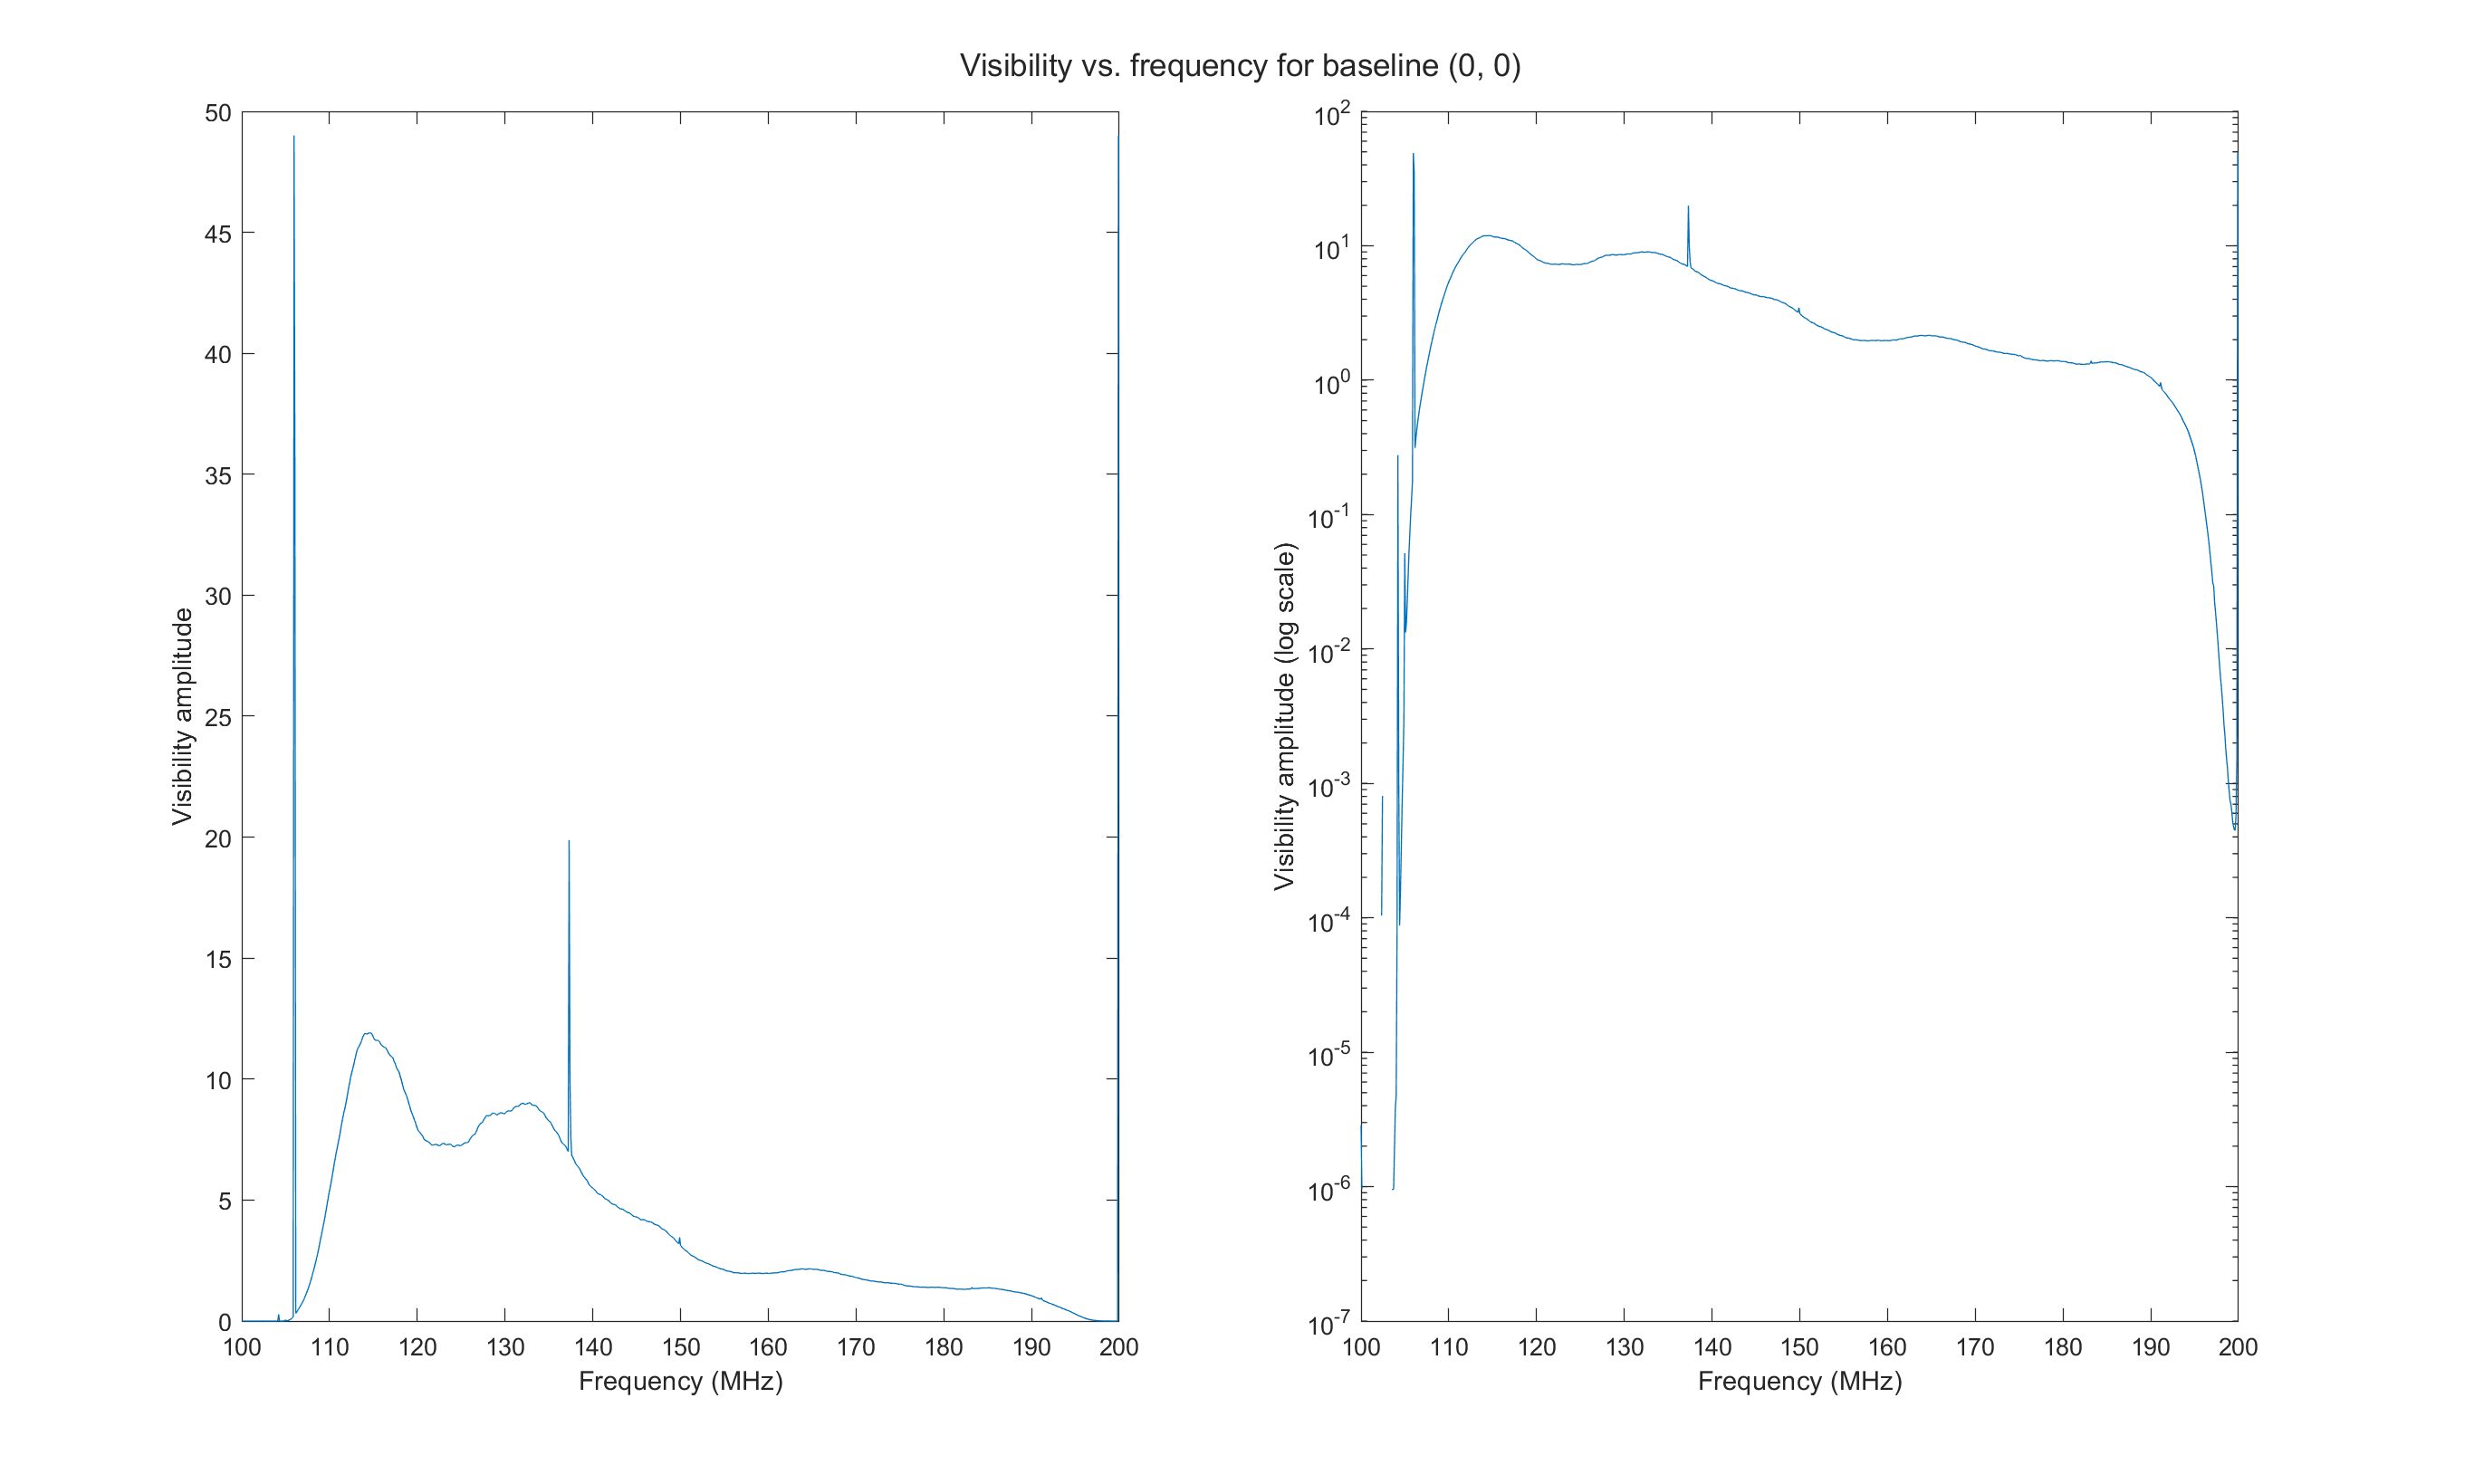

visim1 = visdat2img(visdata1, 1:1024);
amplitude1 = squeeze(sum(visim1, 1));

clf;
t = tiledlayout(1, 2);
nexttile
plot(fs ./ 1e6, amplitude1(1:1024))
ylabel('Visibility amplitude')
xlabel('Frequency (MHz)')
nexttile;
semilogy(fs ./ 1e6, amplitude1(1:1024))
title(t, 'Visibility vs. frequency for baseline (0, 0)')
ylabel('Visibility amplitude (log scale)')
xlabel('Frequency (MHz)')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 0.9]);

We can also plot this as an image where the brightness corresponds to the amplitude of the complex visibility, and the x-axis corresponds to the frequency. This representation will become more useful once we plot more baselines.

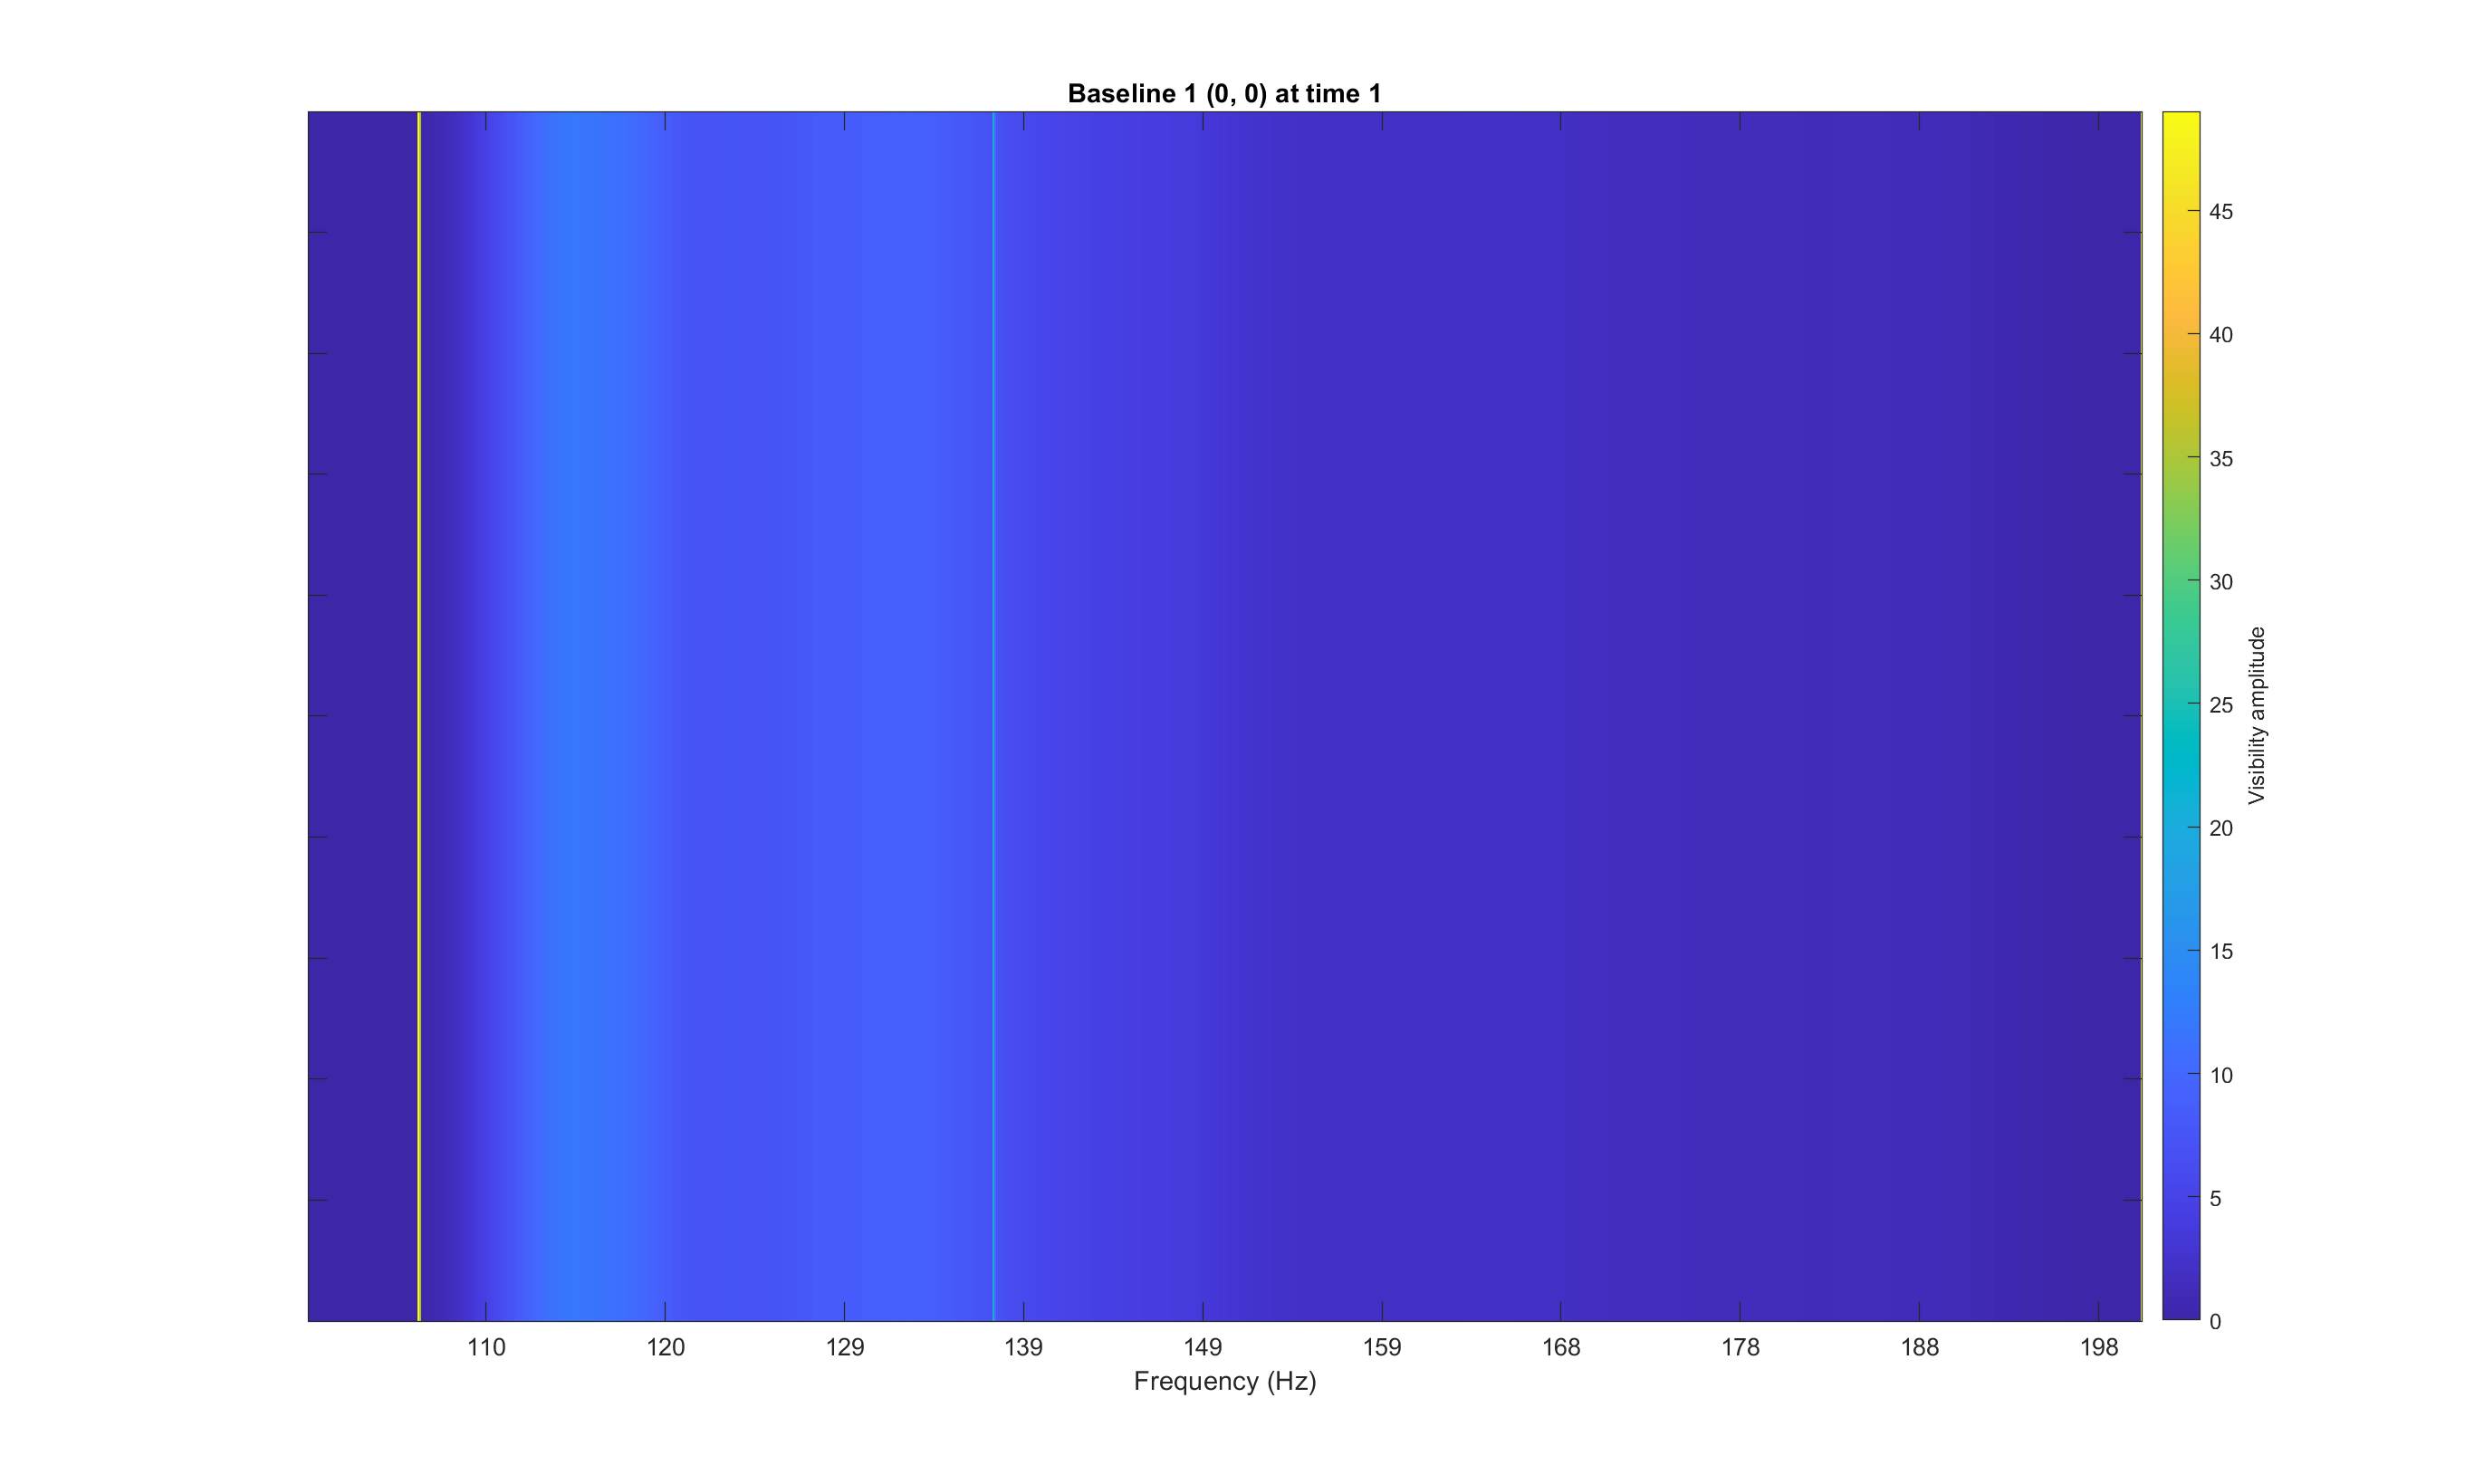

clf;
imagesc(visim1);
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (Hz)');
set(gca,'yticklabel',[])
c = colorbar;
c.Label.String = "Visibility amplitude";
title('Baseline 1 (0, 0) at time 1');

There are clearly some frequencies which correspond to very high values of visibility, shown by the bright vertical lines at around 106 and 137 MHz on both figures. However, there are also some hazy areas denoted by the light blue color which may correspond to background.

We can compare the data from baseline 1 with the data from the next baseline by stacking the plots for each baseline like so:

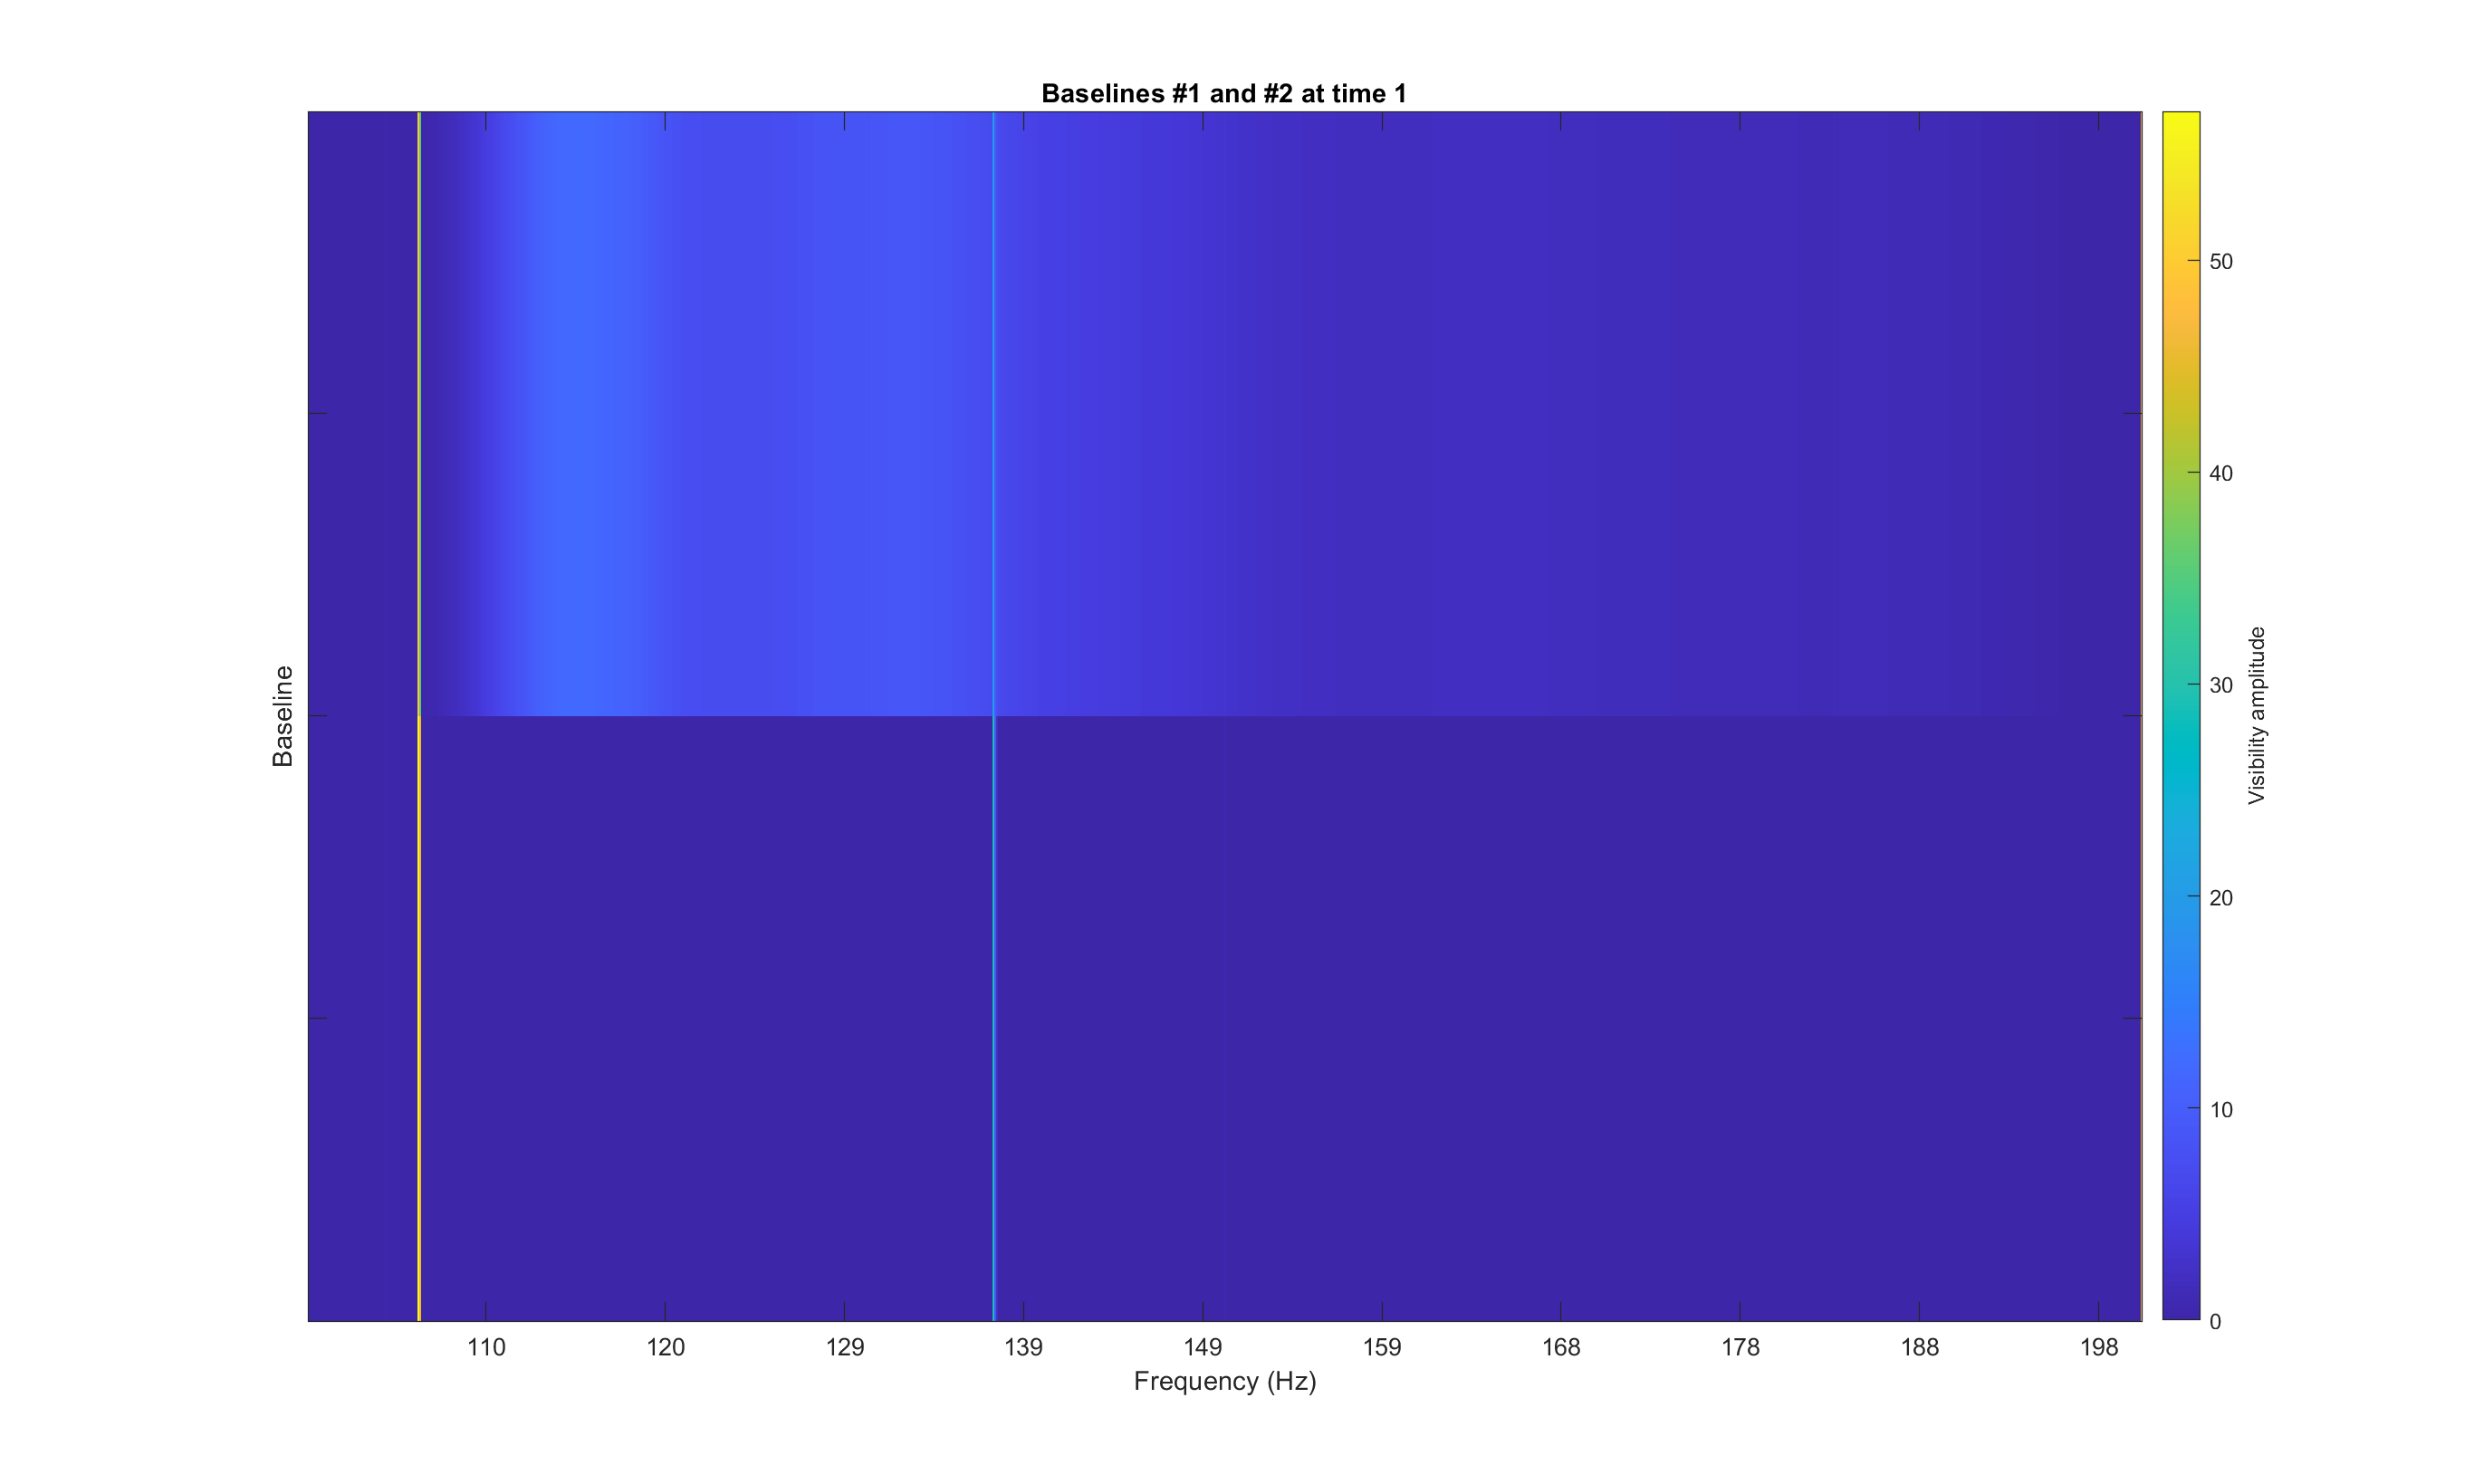

clf;
vismag_im_12 = visdat2img(visdata_12, 1:1024);
imagesc(vismag_im_12');
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (Hz)');
set(gca,'yticklabel',[])
ylabel('Baseline')
c = colorbar;
c.Label.String = "Visibility amplitude";
title('Baselines #1 and #2 at time 1')

While the bright signals at ~106 and ~137 MHz are apparent in both figures, only the top figure contains the hazy blue background.

Let's observe any patterns that arise from plotting data from all baselines for time t=1:

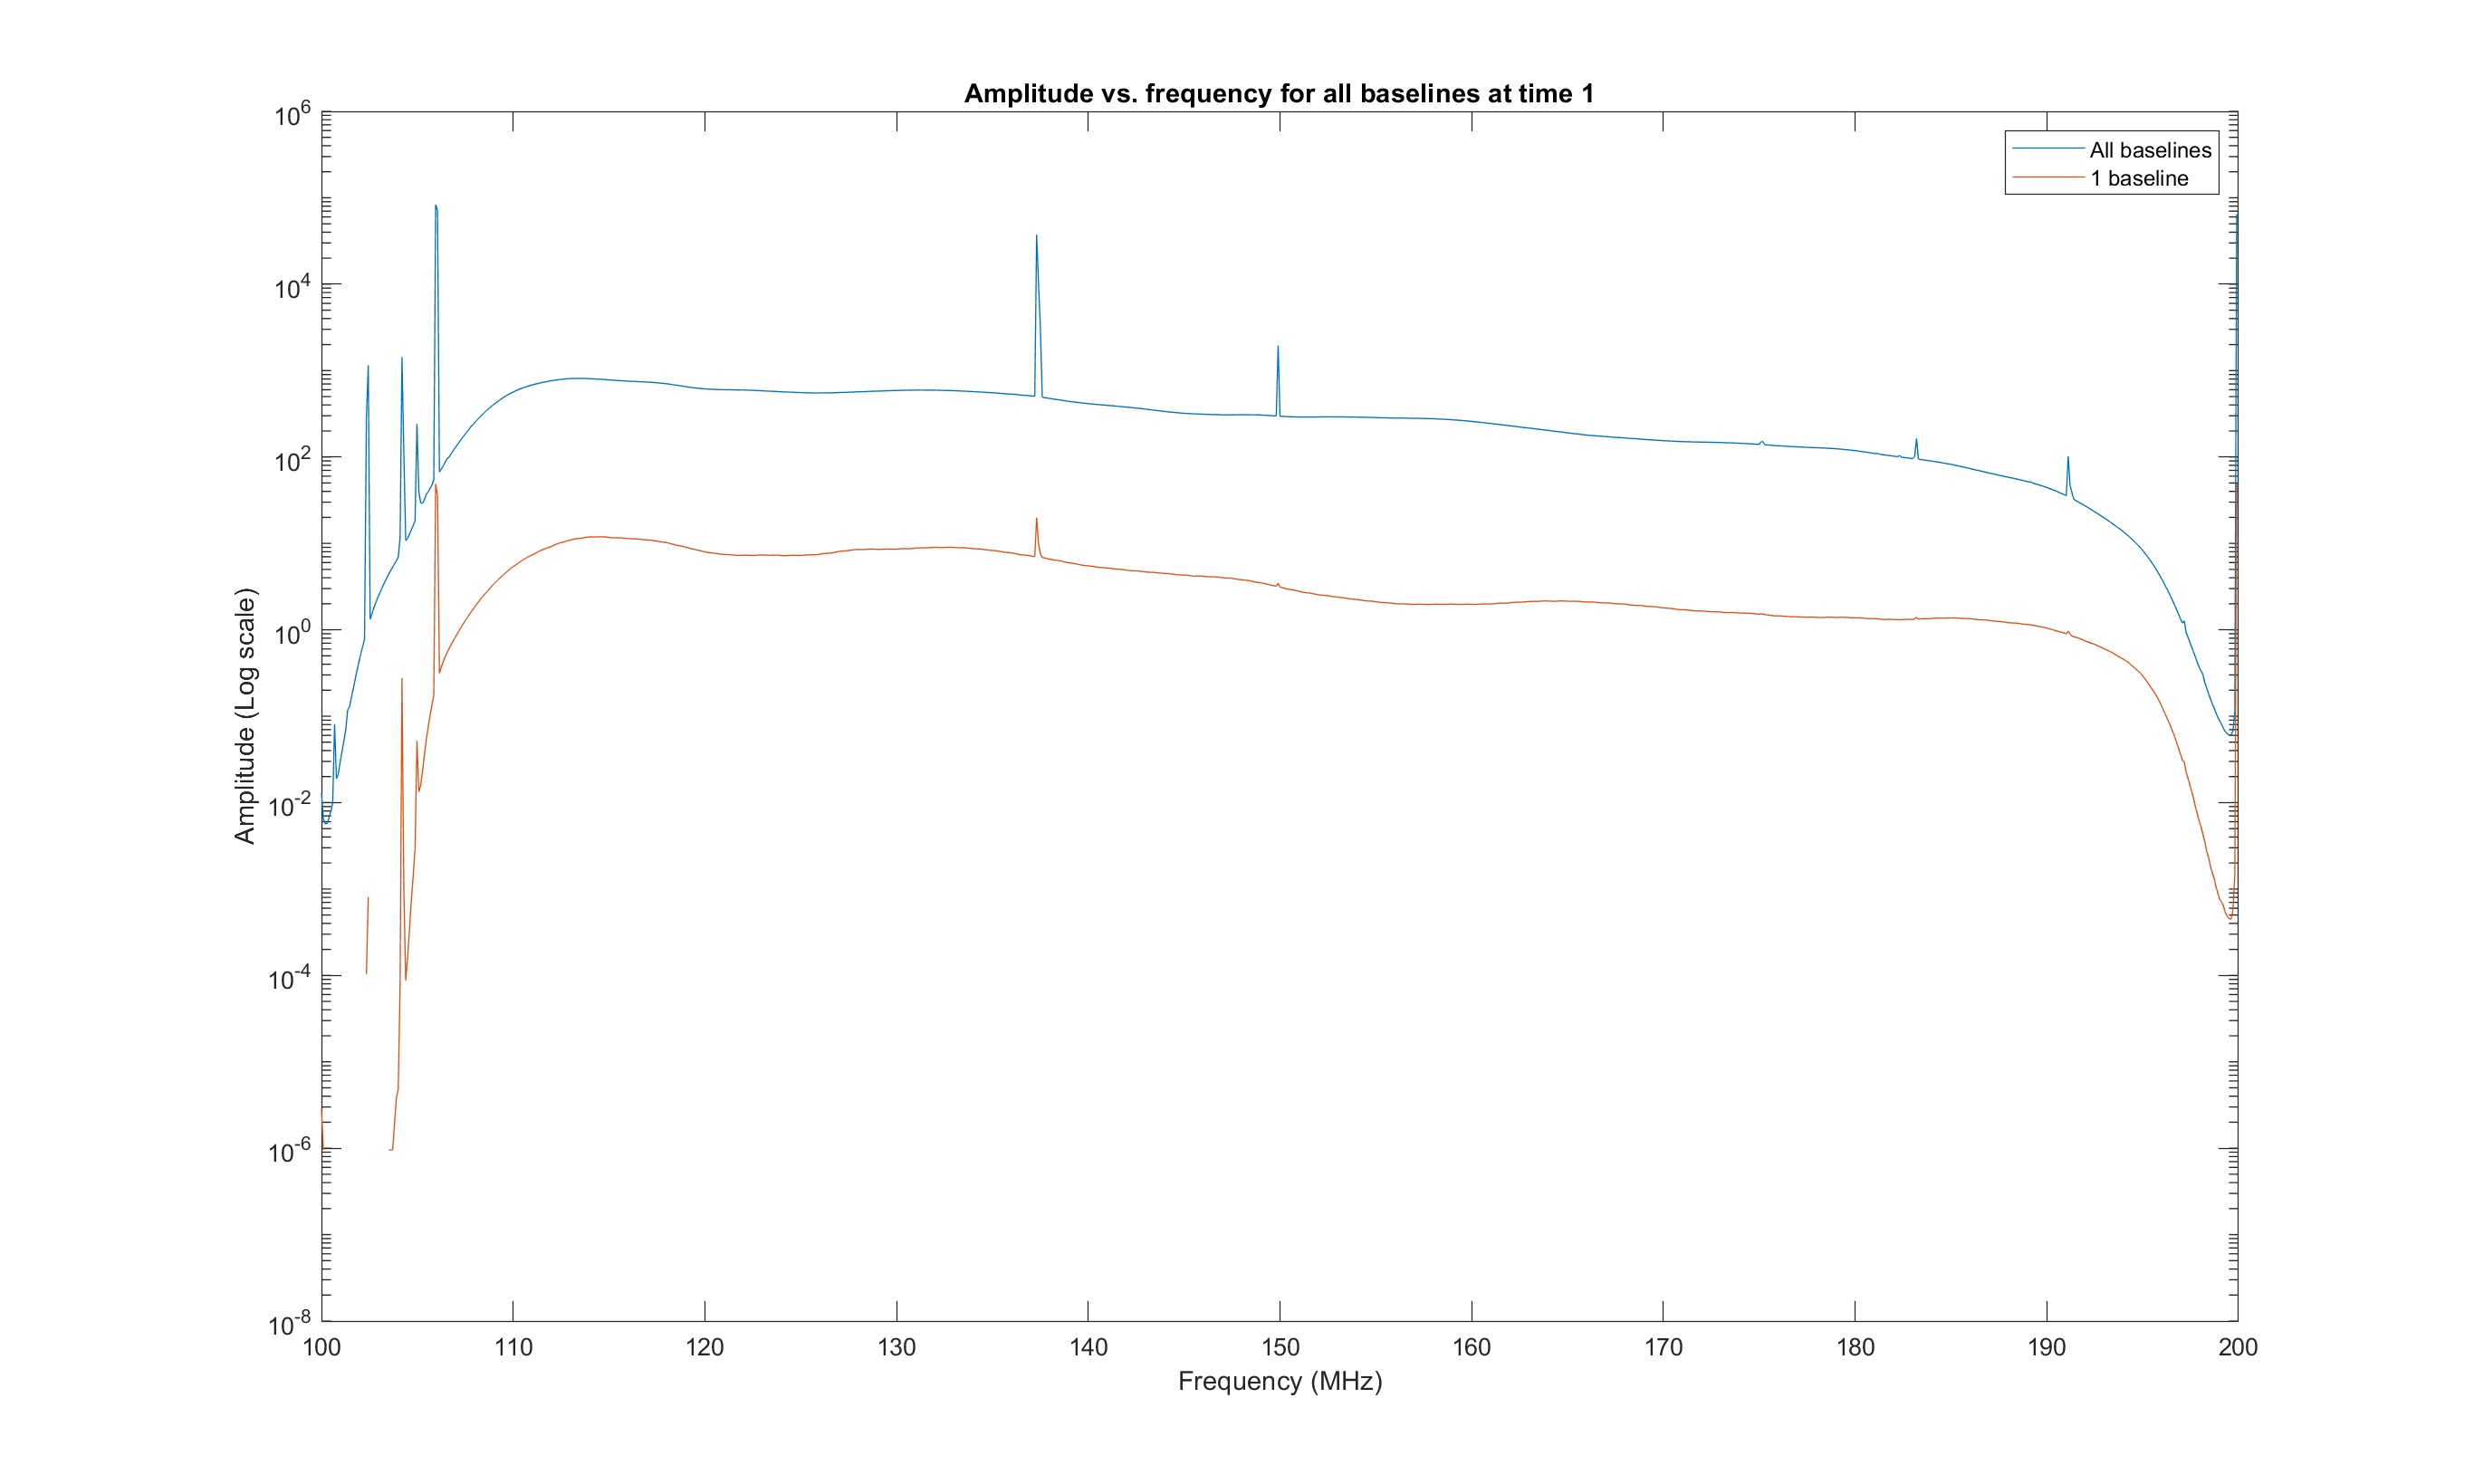

vismag_im_all1 = visdat2img(visdata_all1, 1:1024);
amplitude_all1 = squeeze(sum(vismag_im_all1', 1));
amplitude1 = squeeze(sum(visim1, 1));
clf;
semilogy(fs ./ 1e6, amplitude_all1(1:1024)), hold on;
semilogy(fs ./ 1e6, amplitude1(1:1024))
xlabel('Frequency (MHz)');
ylabel('Amplitude (Log scale)')
title('Amplitude vs. frequency for all baselines at time 1')
legend('All baselines', '1 baseline')

While the overall background is much larger for the sum of all baselines, the signal-to-noise ratio (height of the spikes relative to the background) has improved immensely. Stacking the images from each baseline on top of one another, as before:

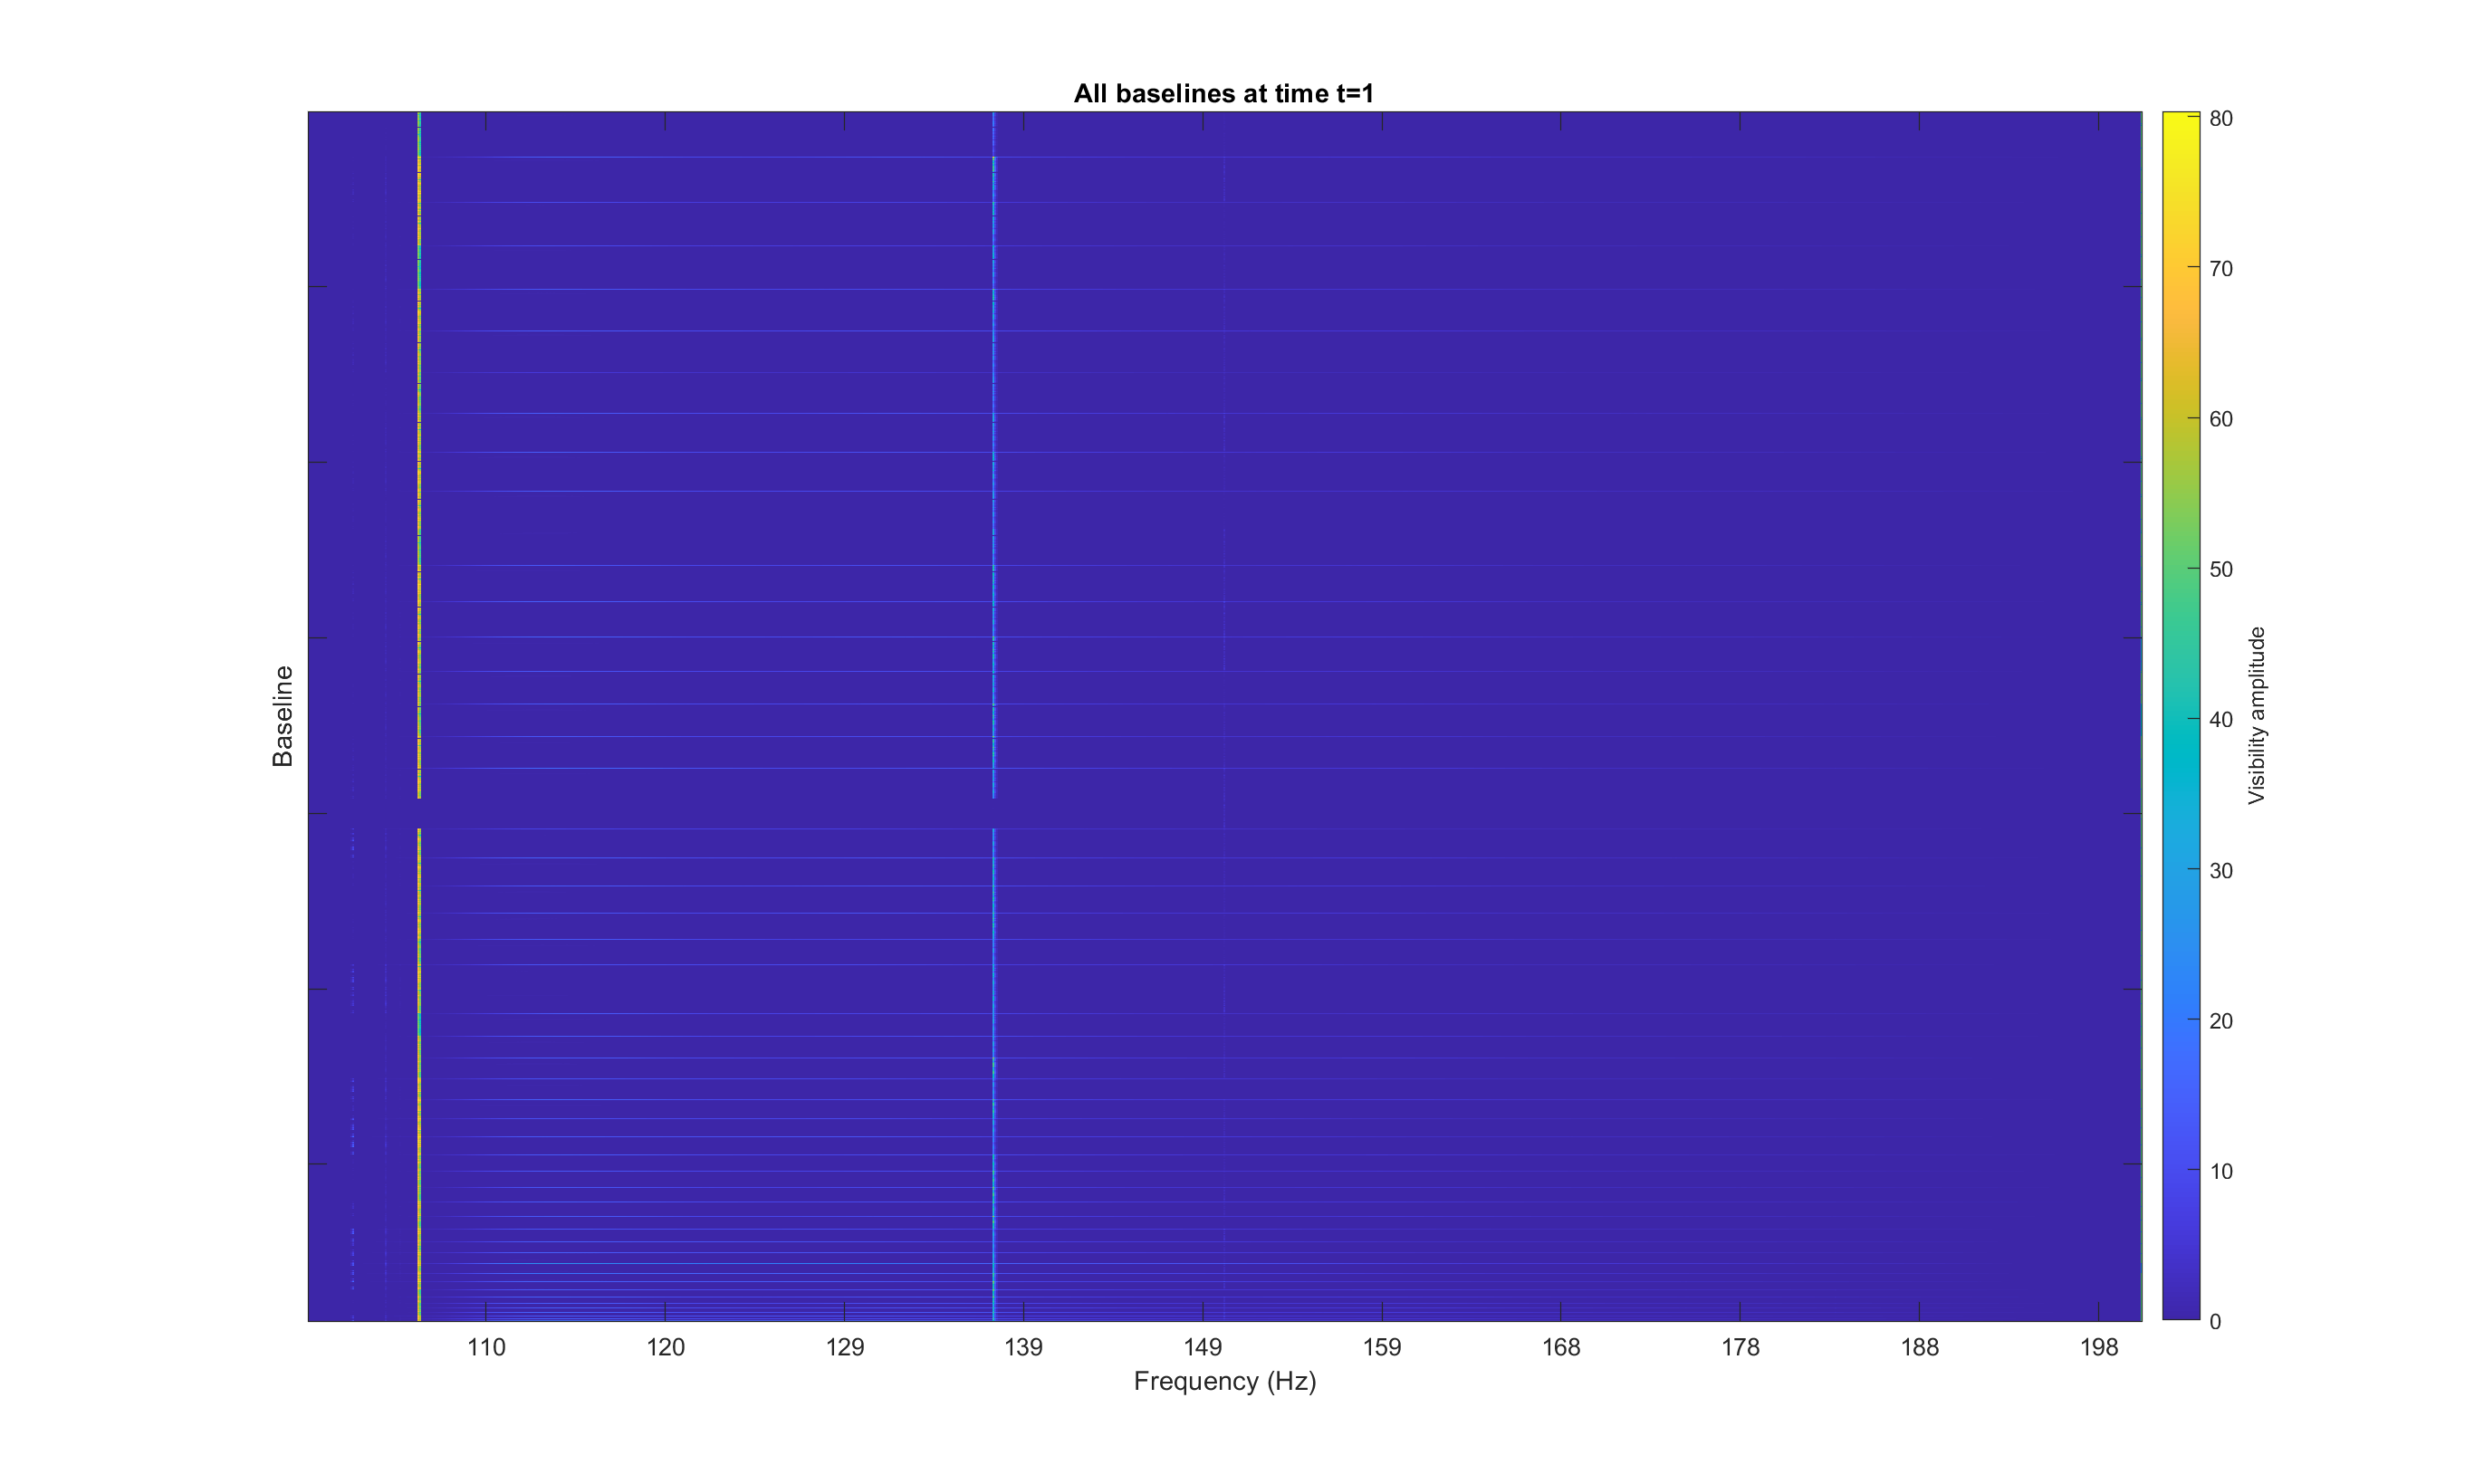

clf;
imagesc(vismag_im_all1');
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (Hz)');
set(gca,'yticklabel',[])
ylabel('Baseline')
c = colorbar;
c.Label.String = "Visibility amplitude";
title('All baselines at time t=1')

The background in this image is clearly reduced compared to the first two images; the hazy blue background is gone. However, in its place are these thin blue streaks, which correspond to individual baselines with the anomalous background. Since the first baseline corresponding to (0, 0) exhibited this unusual background, we might assume that this is a phenomena that occurs when the correlator combines data from the same antenna. Let us call these baselines (n,n) pairs to denote that data from an antenna is being correlated with itself. We can see if removing these data points will improve the data quality:

commonpair_indices = baselines(:, 1) == baselines(:, 2);
common_pairs = baselines(commonpair_indices, :)'

common_pairs = 2×52 int64 matrix
     0     1     2    11    12    13    14    23    24    25    26    27    36    37    38    39    40    41    50    51    52    53    54    55    65    66    67    68    69    70    71    82    83    84    85    86    87    88    98   120   121   122   123   124   136   137   138   139   140   141
     0     1     2    11    12    13    14    23    24    25    26    27    36    37    38    39    40    41    50    51    52    53    54    55    65    66    67    68    69    70    71    82    83    84    85    86    87    88    98   120   121   122   123   124   136   137   138   139   140   141


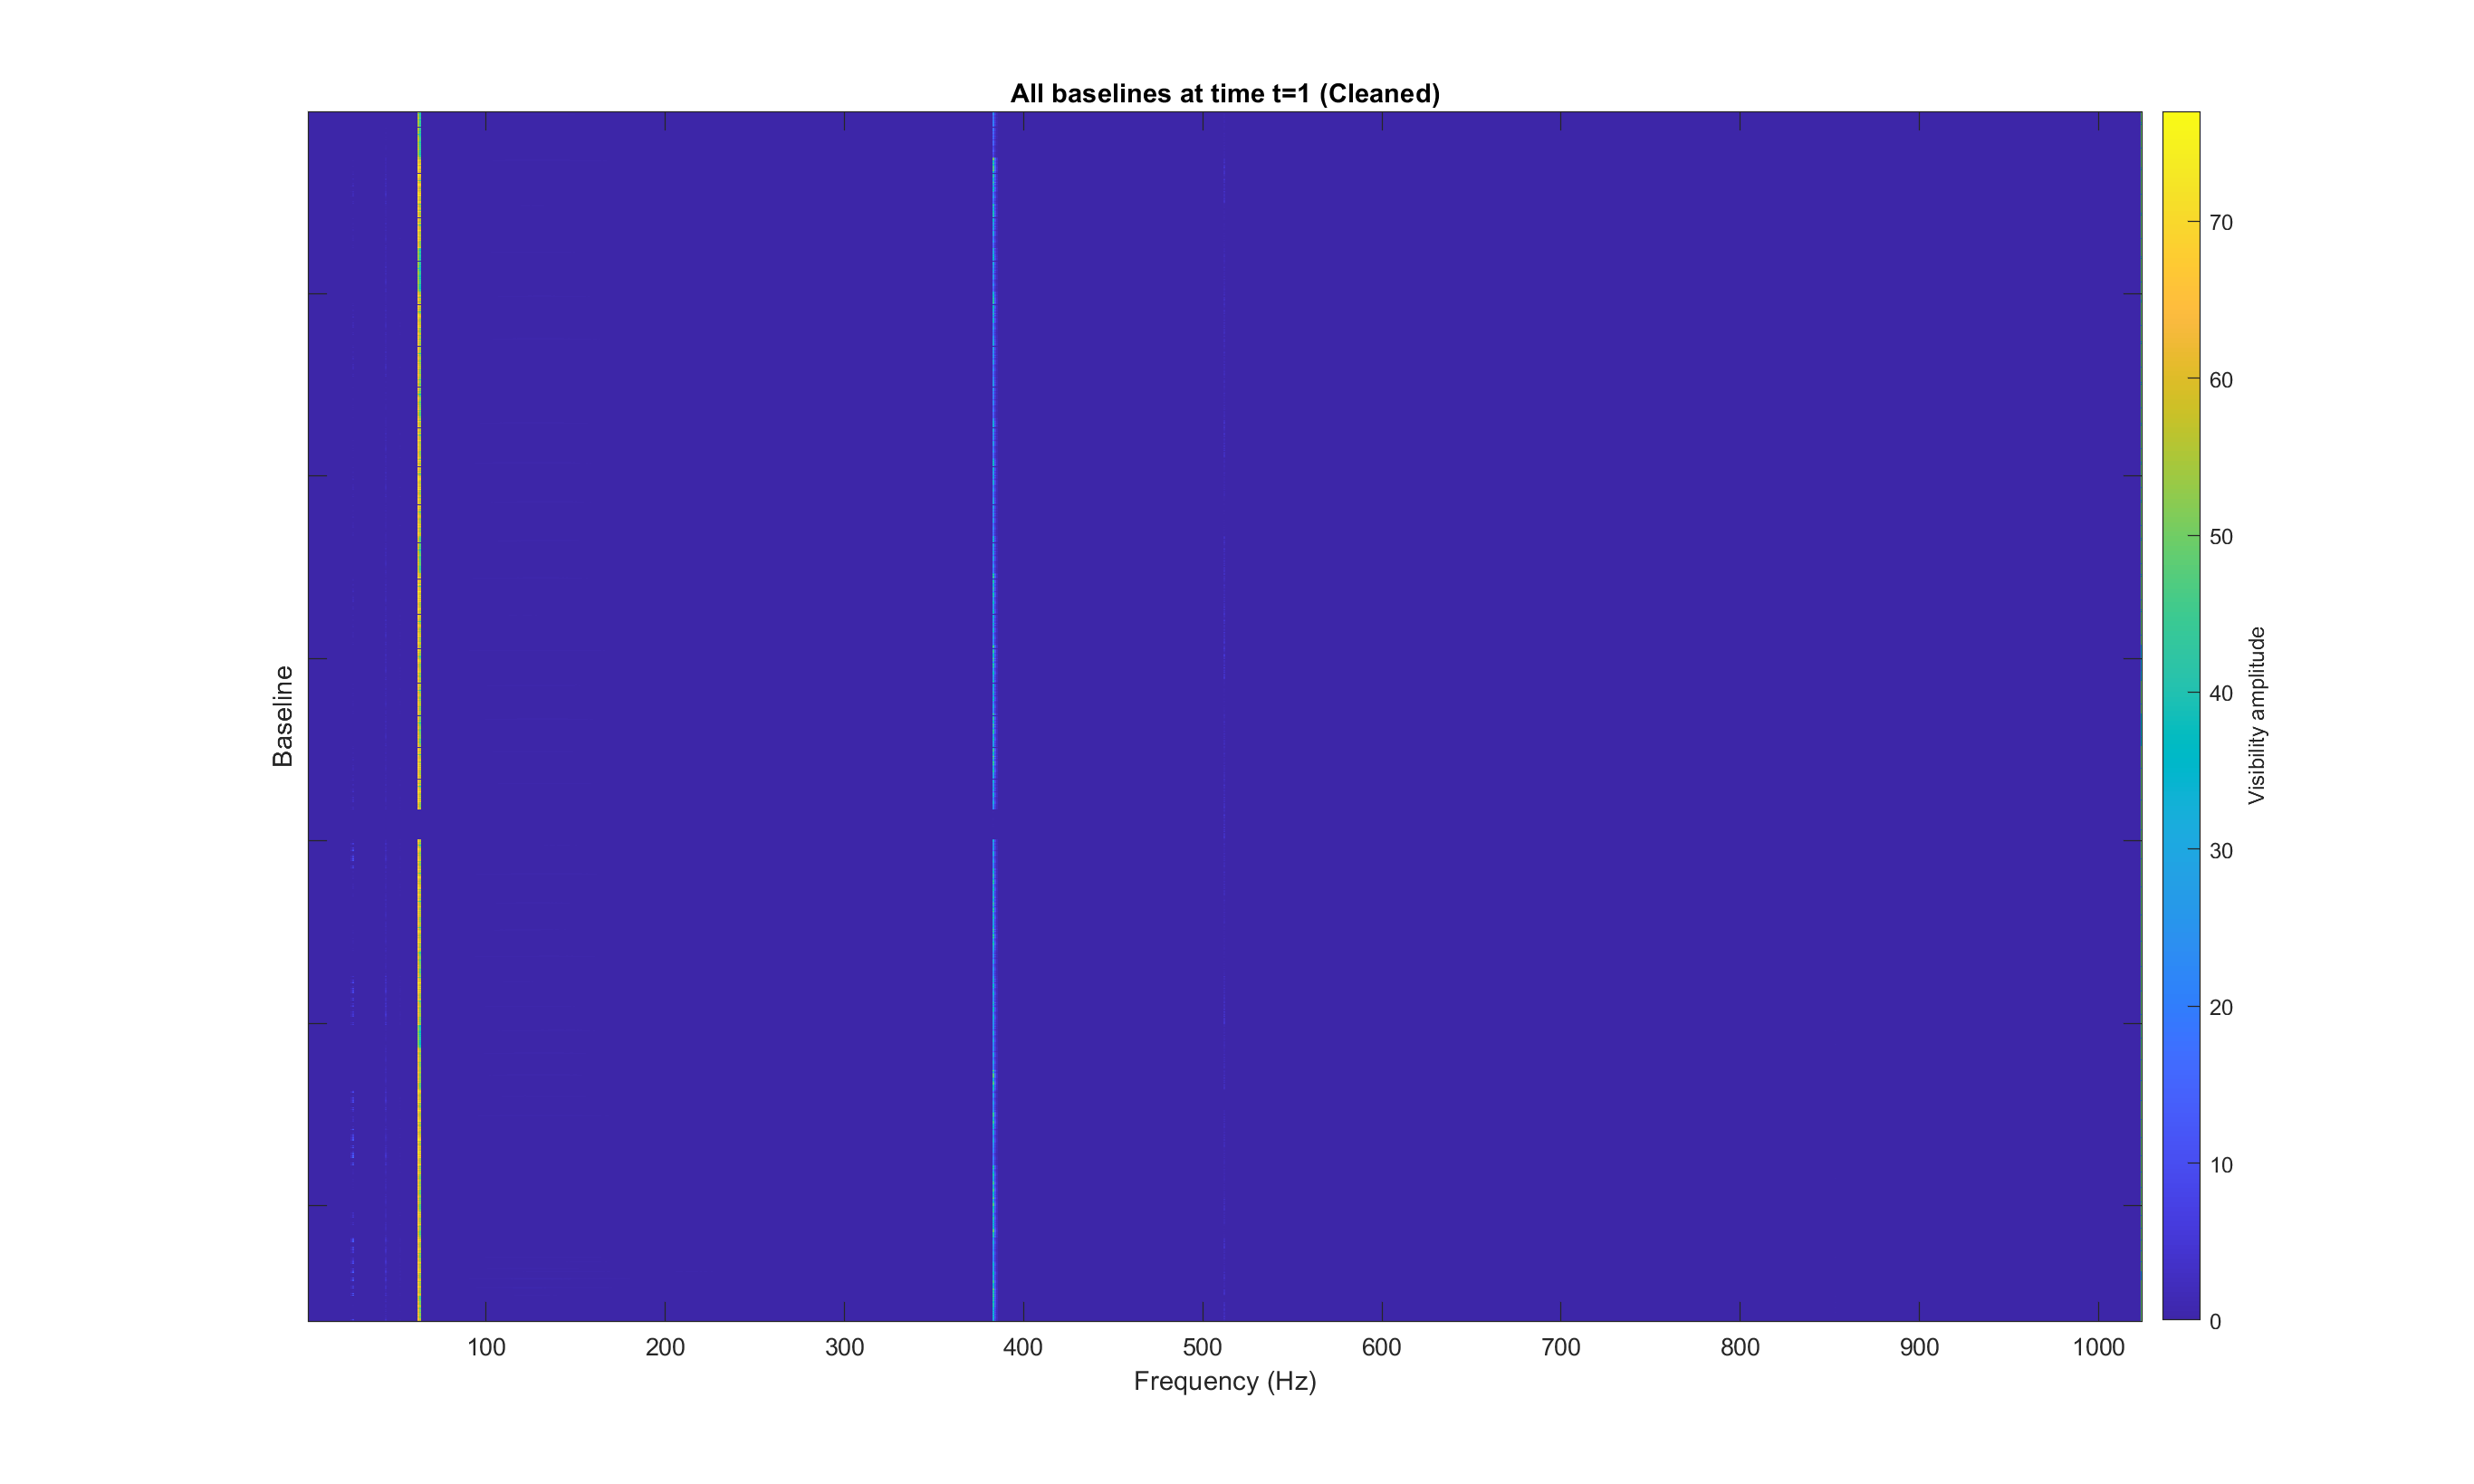

clean_img = vismag_im_all1(:, ~commonpair_indices);

clf;
imagesc(clean_img')
xlabel('Frequency (Hz)');
set(gca,'yticklabel',[])
ylabel('Baseline')
c = colorbar;
c.Label.String = "Visibility amplitude";
title('All baselines at time t=1 (Cleaned)')

It seems like we were successful in removing the signal contamination from the data. However, the exact process from which this anomalous background occurs is unknown at this point.

Finally, we can plot the data we have worked with so far on the same set of axes to see how our noise is reduced:

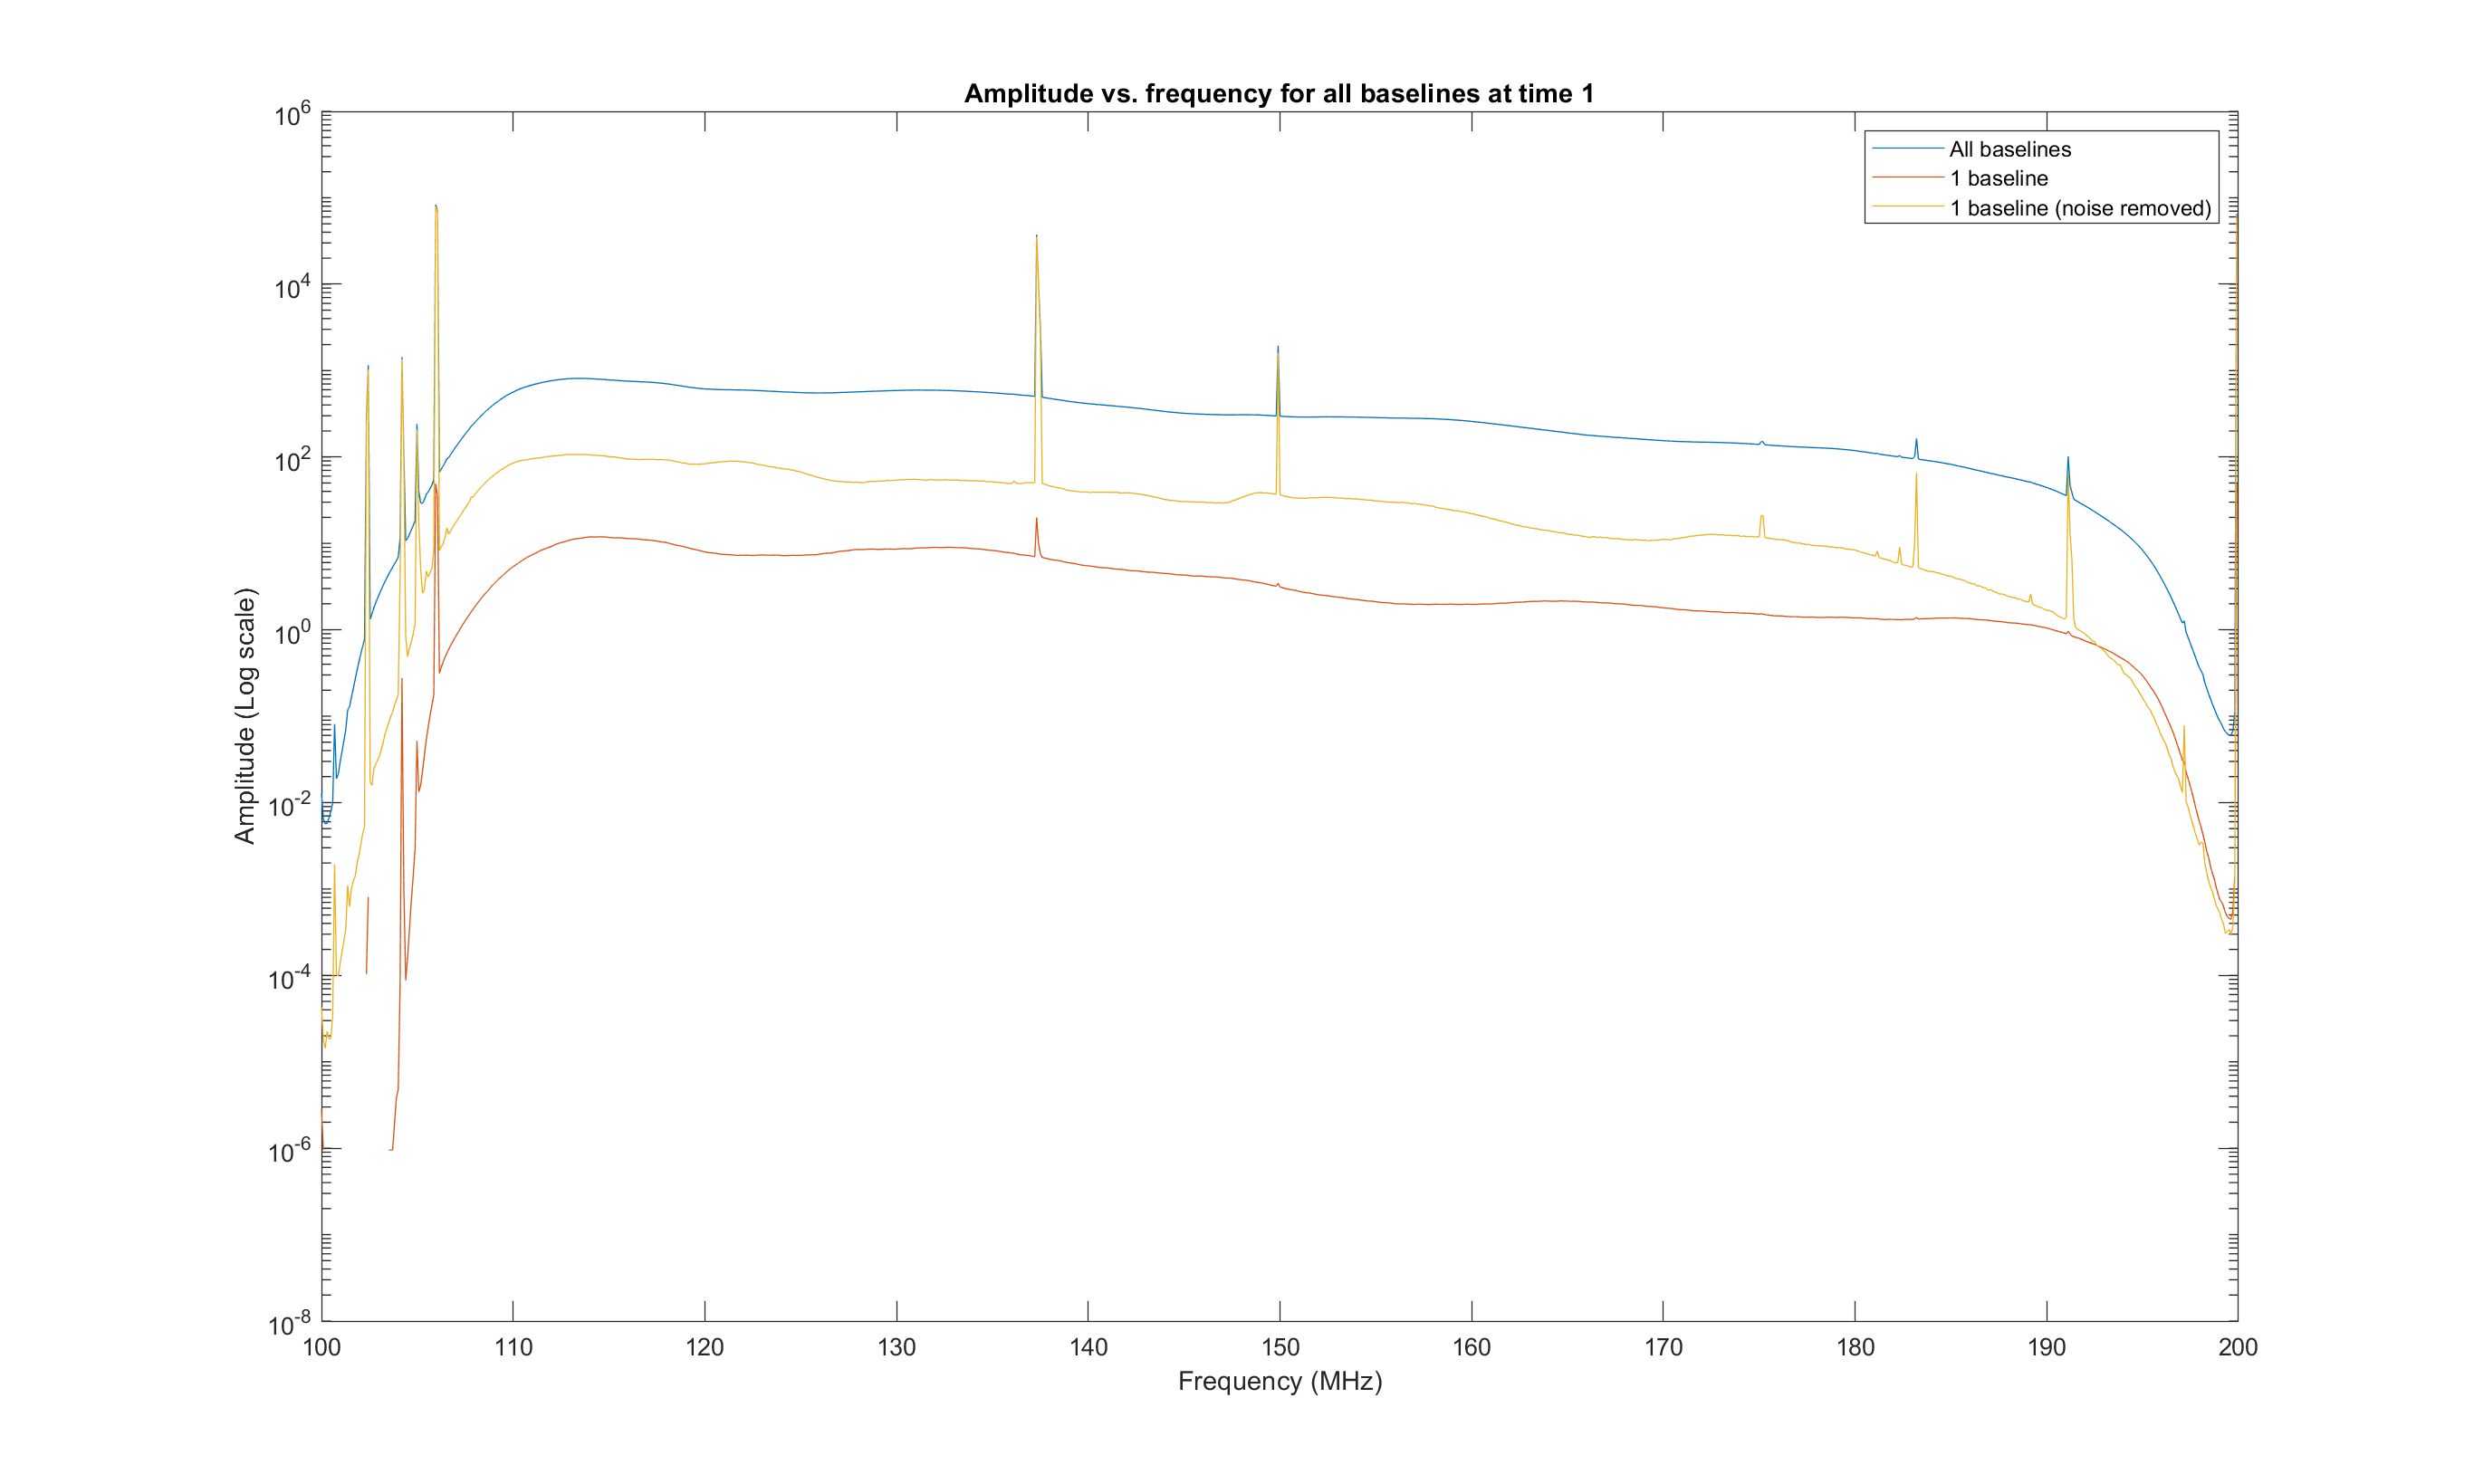

clean_amplitude = squeeze(sum(clean_img', 1));
clf;
semilogy(fs ./ 1e6, amplitude_all1(1:1024)), hold on;
semilogy(fs ./ 1e6, amplitude1(1:1024))
xlabel('Frequency (MHz)');
ylabel('Amplitude (Log scale)')
title('Amplitude vs. frequency for all baselines at time 1')
semilogy(fs ./ 1e6, clean_amplitude(1:1024));
legend('All baselines', '1 baseline', '1 baseline (noise removed)')

Note that the signal-to-noise ratio improves as:

- Data from more baselines are added, and

- The anomalous background data from the (n,n) baselines is removed

function visimg = visdat2img(visdata, freq_range)
    vismagnitude = sqrt(visdata.r(1, freq_range, 1, :).^2 + visdata.i(1, freq_range, 1, :).^2);
    visimg = squeeze(vismagnitude(1, freq_range, 1, :));
end